# Pop Music Analysis: Predicting the Next Greatest Hit Artist

In recent weeks, we've explored using machine learning and AI tools for data analysis and prediction. For this final project, you'll build and train a prediction model to determine if an emerging music artist is on a similar trajectory to some of the greatest pop music artists.

Your task involves:

- **Data Collection:** Find and import data on various music artists.

- **Model Selection:** Choose a machine learning model from those we've covered in class.

- **Parameter Determination:** Decide on the parameters that will help identify similarities and differences between the artists.

## Step 1: Define Success

The primary objective of this project is to analyze the early career trajectory of emerging pop artist Tyla and compare it to the early careers of three established pop artists: Ariana Grande, Beyoncé, and Taylor Swift. By examining various metrics and patterns from the first three to five years of their careers, we aim to determine which established artist Tyla's career path most closely resembles. Ariana Grande, known for her powerful vocals and broad appeal, has become a global pop sensation since her debut, with multiple chart-topping albums and singles, and a strong presence on social media and streaming platforms. Beyoncé, originally the lead singer of Destiny’s Child, has successfully transitioned to a solo career, earning numerous awards and accolades while establishing herself as a cultural icon. Taylor Swift, initially known for her country music roots, has seamlessly crossed over to pop music, consistently producing hit albums and maintaining a loyal fan base. For this project, we will collect and analyze data on these artists' music, social media activity, and public reception using tools such as the Spotify API, and apply machine learning techniques to determine the similarities and differences in their career trajectories.

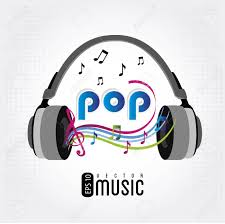

## Step 2: Import Your Music Data

Data for all mentioned artists will be imported using the Spotify API, as demonstrated in lessons 3 and 5. While various attributes can be chosen for analysis, we will specifically focus on the duration and danceability of the artists' songs. I selected these variables because I believe they are key indicators of an artist's success. However, you are welcome to explore other variables or multiple variables to see which ones best predict an artist's success.

To configure the API to gather the necessary data, we will utilize the following two endpoints:

- **'https://api.spotify.com/v1/albums/{album id}/tracks' **to access the artist's name, duration, and track ids in each album. 

- **'https://api.spotify.com/v1/audio-features/{track id}' **to access each tracks unique features such as danceability. 

From the second endpoint you can access many interesting metrics such as the song's energy, instrumentalness, liveness, and other song characteristics. It is recommend that you explore this endpoint in the Spotify website since it might be useful when designing your own AI model. 

The API will be run in multiple sections. The first section requires you to input your Client ID and Client Secret to obtain an access token, which will allow you to communicate with the Spotify API and gather data (as seen in section 3).

% RUN THIS CODE AS IS
clc; clear;

% Copy in your own credentials.
clientID = 'f8afab8e2efe42118323e37be22ad76e'; % Replace with your actual client ID
clientSecret = 'efef2958b97147f0ab0af6b335a97bfa'; % Replace with your actual client secret

% Create the URL for token retrieval
url = 'https://accounts.spotify.com/api/token';

% Encode the client ID and client secret in base64
authString = matlab.net.base64encode([clientID ':' clientSecret]);

% Set the options for the HTTP request
options = weboptions('RequestMethod', 'post', 'MediaType', ...
    'application/x-www-form-urlencoded','HeaderFields', {'Authorization', ['Basic ' authString]});

% Set the POST data
postData = 'grant_type=client_credentials';

% Make the POST request to retrieve the access token
response = webwrite(url, postData, options);

% Extract the access token from the response
Token = response.access_token;

% Display the access token (you can process it further as needed)
disp(['Access Token: ' Token]);

Access Token: BQDcrdPoNOPXpn-i95Qkab-LAYUnns3G9iXxoQvsJLgDH2V6qiSyjPBwpOYNv6hkqHTCEMBwxH-qKc9_aAt6hpbJuOyne1bp0W5M5ocSRTbOVNyUPE0


The next code block aims to retrieve albums for each of the artists using their respective album IDs stored in a table. For Taylor Swift, Beyoncé, and Ariana Grande, the first album of each artist will be utilized as training data for building the predictive model. The subsequent albums of these three successful artists will serve to validate and assess the accuracy of the model. However, for Tyla, her album will solely be used to compare his music against that of the other three artists.

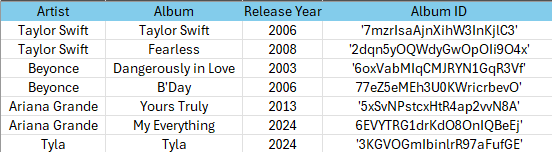

During this process, the code will extract crucial details such as the artist's name, the duration of each song, and the track ID of every song within the selected albums. The track ID, a unique string of characters assigned by Spotify to each song, plays a pivotal role as it enables the retrieval of distinct audio features specific to each track, such as danceability.

% Stores the album' IDs 
% The order in which IDs are stored in the variable affects the order they are retrieved in. 
% The first 4 IDs are for the albums in the white rows of the table above and the
% last 3 IDs are for the albums in the blue rows.
albumIDs = {'7mzrIsaAjnXihW3InKjlC3';'2dqn5yOQWdyGwOpOIi9O4x';'6oxVabMIqCMJRYN1GqR3Vf';'77eZ5eMEh3U0KWricrbevO';
    '5xSvNPstcxHtR4ap2vvN8A'; '6EVYTRG1drKdO8OnIQBeEj'; '3KGVOGmIbinlrR97aFufGE'};

% Initialize arrays to store song details
allArtists = {};
durations = [];
TrackIDs = {};
danceability = [];

% Loop over each album ID
for j = 1:numel(albumIDs)
    % Construct the URL for getting the tracks of the album
    url = ['https://api.spotify.com/v1/albums/', albumIDs{j}, '/tracks?limit=50'];
    % Set up the web options with the access token
    options = weboptions('HeaderFields', {'Authorization', ['Bearer ', Token]});
    % Make the GET request to retrieve tracks of the album
    response = webread(url, options);

    % Get artist name, song duration, and track ID
    for i = 1:response.total
        allArtists = [allArtists; response.items(i).artists.name];
        durations = [durations;response.items(i).duration_ms];
        TrackIDs = [TrackIDs; response.items(i).id];
    end
end
disp('Albums retrieved successfully!')

Albums retrieved successfully!


This loop will retrieve the danceability of each song using the track IDs. 

**Note: This section may run slowly depending on the number of iterations it has to complete, which is dependent on the number of songs in the album being analyzed.**

% Loop over each track to gets its audio features
for k = 1:numel(TrackIDs)
    url2 = ['https://api.spotify.com/v1/audio-features/', TrackIDs{k}];
    options2 = weboptions('HeaderFields', {'Authorization', ['Bearer ', Token]});
    Features = webread(url2, options2);
    danceability = [danceability;Features.danceability];
end
disp('Track danceability has been retrieved!')

Track danceability has been retrieved!


Let's organize the data retrieved from the Spotify API. The process involves standardizing the names of the artists and storing the data in a structured table. First, we will address any inconsistencies in the formatting of artist names. This involves cleaning and standardizing the names to ensure uniformity, such as converting all names to lowercase and replacing underscores with spaces.

After standardizing the names, we will create a table to store the relevant information for each song. This table will include attributes such as duration, danceability, and the standardized artist names. By organizing the data in a table, we make it easier to access, manipulate, and analyze the information. This structured approach ensures that our dataset is clean and ready for further analysis or modeling.

% Some songs were collaborations, so they include more than one artist name.
% We only want the variable 'allArtists' to contain the names of the main artists: 'Taylor Swift', 'Beyonce', 'Ariana Grande', and 'Tyla'.

% Assign the main artist names to the 'allArtists' array
allArtists(1:28) = {'Taylor Swift'};
allArtists(29:54) = {'Beyonce'};
allArtists(55:81) = {'Ariana Grande'};
allArtists(82:95) = {'Tyla'};

% Store the training data for Taylor Swift, Beyonce, and Ariana Grande. This will only consist of rows 71 to 117.
% Create a table 'SongDetails3' with data for Taylor Swift (rows 16-28), Beyonce (rows 35-44), and Ariana Grande (rows 58-81)
SongDetails = table(allArtists([16:28, 35:44, 58:81]), durations([16:28, 35:44, 58:81]), danceability([16:28, 35:44, 58:81]));
disp('Table has been made successfully!')

Table has been made successfully!


## Step 3: Identifying Your Variables

To analyze the early career trajectories of emerging pop artist Tyla alongside established artists Ariana Grande, Beyoncé, and Taylor Swift, we focus on two key variables: song duration and danceability. Song duration will reveal stylistic trends and format preferences, gathered via the Spotify API endpoint `'https://api.spotify.com/v1/albums/{album_id}/tracks'`. Danceability, derived from `'https://api.spotify.com/v1/audio-features/{track_id}'`, measures how engaging each track is for dancing, reflecting its rhythm and tempo. These metrics will help us compare the musical evolution and audience reception of Tyla and the established artists during their initial years in the industry.

## Step 4: Split Data into Training and Testing Sets

The code below takes the data from the table `SongDetails` and separates it into the desired files. It also stores the data for Tyla into a file called SongDetails2.

% Names each column in the 'SongDetails' table to be 'Artist', 'Duration', and 'Danceability'
SongDetails.Properties.VariableNames = {'Artist', 'Duration', 'Danceability'};

% Write the 'SongDetails' table to an Excel file named 'Successful_pop_Artists3.xlsx'
writetable(SongDetails, 'Successful_pop_Artists3.xlsx');

% Store the data for Tyla. Her data is in rows 82 to 95. Create a table 'SongDetails2' with his data
SongDetails2 = table(allArtists(82:95), durations(82:95), danceability(82:95));

% Names each column in the 'SongDetails2' table to be 'Artist', 'Duration', and 'Danceability'
SongDetails2.Properties.VariableNames = {'Artist', 'Duration', 'Danceability'};

% Write the 'SongDetails2' table to an Excel file named 'New_pop_Artist.xlsx'
writetable(SongDetails2, 'New_pop_Artist.xlsx');

% Store the testing data for Taylor Swift, Beyonce, and Ariana Grande. This will only consist of rows 71 to 117.
% Create a table 'SongDetails3' with data for Taylor Swift (rows 1-15), Beyonce (rows 29-34), and Ariana Grande (rows 45-57)
SongDetails3 = table(allArtists([1:15, 29:34, 45:57]), durations([1:15, 29:34, 45:57]), danceability([1:15, 29:34, 45:57]));

% Names each column in the 'SongDetails3' table to be 'Artist', 'Duration', and 'Danceability'
SongDetails3.Properties.VariableNames = {'Artist', 'Duration', 'Danceability'};

% Write the 'SongDetails3' table to an Excel file named 'TestData.xlsx'
writetable(SongDetails3, 'TestData.xlsx');

% Display a message indicating that the Excel files have been created successfully
disp('Excel files have been created!')

Excel files have been created!


## Step 5: Finding Your Model

The selection of an appropriate model hinges on whether success is defined as a continuous value or a categorical outcome. In this analysis, where the goal is to compare Tyla's songs with those of three successful pop artists, employing a classification model proves to be the most fitting approach.

**Opting for the K-Nearest Neighbors (KNN) Model:**As discussed in Lesson 5, the KNN model stands out as a robust choice for classification tasks due to its simplicity and adaptability across various problem types. KNN operates by classifying new data points according to the majority class among their nearest neighbors in the feature space.

**Key Functions Utilized:**To implement the KNN model in MATLAB, we will leverage two core functions:

- **fitcknn():** This function is essential for training the KNN model using the training data of successful pop artists. It allows the model to learn and internalize the patterns and relationships present in the data.

- **predict():** Following training, the predict function will be employed to classify new data points based on the insights gained from the trained KNN model.

## Step 6: Fitting a Model to your Data

Let's fit a KNN model using the data in the file** PopArtist**`3.xlsx`. We will make sure that model is working by using the function `predict() `to predict an artist based on a song duration of 22226 and danceability of 0.5. 

% Read the data from the Excel file "Sucessful_pop_Artists3.xlsx" into the table variable 'PopArtist3'
PopArtist3 = readtable("Sucessful_pop_Artists3");

% Fit a k-nearest neighbors (KNN) classification model using the data
% 'PopArtist3' contains columns 'Artist', 'Duration', and 'Danceability'.
% "Artist" is the label we want to predict based on "Duration" and "Danceability".
% Set the number of neighbors (k) to 6 for the KNN model.
knnmodel = fitcknn(PopArtist3, "Artist", "NumNeighbors", 6);

% Test the model by making predictions based on new data points.
% Here, [22226, 0.8] represents new data for "Duration" (22226 milliseconds)
% and "Danceability" (0.8). This data is passed to the 'predict' function
% along with the trained 'knnmodel' to predict the corresponding "Artist".
predicted = predict(knnmodel, [22226, 0.5]);

% Display the predicted result
disp("Predicted Artist:");

Predicted Artist:


disp(predicted);

    {'Ariana Grande'}



## Step 7: Run Model Using Your Test Dataset

Let's apply the trained KNN classification model to Tyla's songs in order to evaluate its accuracy in Step 8. This step will help us assess how well the model categorizes Tyla's music relative to the successful pop artists used for training.

% Read the verification data from the Excel file into a table
TestData = readtable('TestData.xlsx');

% Use the trained KNN model to predict the artists for the verification data

% Explanation:
% - 'TestData' is a table containing columns 'Artist', 'Duration', and 'Danceability'
%   which were previously stored in 'TestData.xlsx'.
% - 'knnmodel' is a trained KNN classification model obtained from the previous steps,
%   using successful pop artists' data to learn patterns in 'Duration' and 'Danceability'.
% - The 'predict' function applies the trained model ('knnmodel') to predict the 'Artist'
%   for each row in 'TestData', based on the values of 'Duration' and 'Danceability' for
%   each song.

predictions = predict(knnmodel, TestData);

% Display the predictions

% Explanation:
% - Display the predicted artists for the verification data.
% - Each entry in 'predictions' corresponds to the predicted 'Artist' for the respective row
%   in 'TestData', based on the trained KNN model.

disp('Predictions for Verification Data:');

Predictions for Verification Data:


disp(predictions);

    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Taylor Swift' }
    {'Taylor Swift' }
    {'Taylor Swift' }
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Ariana Grande'}
    {'Beyonce'      }
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Beyonce'      }
    {'Beyonce'      }
    {'Beyonce'      }
    {'Beyonce'      }
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Ariana Grande'}
    {'Beyonce'      }
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Taylor Swift' }
    {'Beyonce'      }
    {'Ariana Grande'}
    {'Beyonce'      }
    {'Ariana Grande'}
    {'Taylor Swift' }



## Step 8: Evaluate the Model

Let's evaluate the model by calculating the accuracy, misclassification rate, and making a confusion matrix. To calculate the accuracy we compare the predictions from the previous step to the data in the file `TestData.xlsx`.

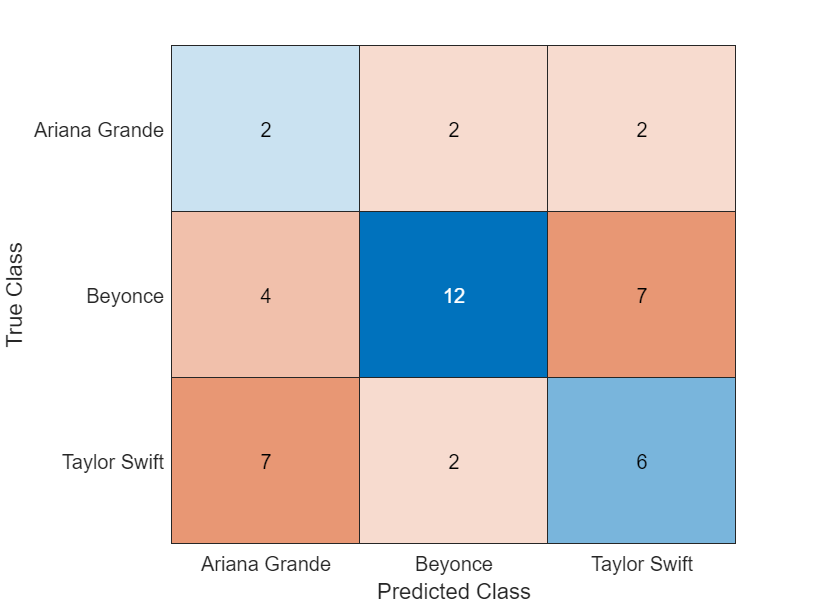

% Check if the predictions are correct and calculate accuracy

% Explanation:
% - 'predictions' contains the predicted artists for the verification data.
% - 'TestData.Artist' contains the actual artists from the verification data.
% - 'cellfun(@isequal, predictions, TestData.Artist)' compares each predicted
%   artist with the actual artist and returns logical values indicating whether
%   they are equal.
iscorrect = cellfun(@isequal, predictions, TestData.Artist);

% Calculate accuracy
% Explanation:
% - 'accuracy' is calculated by dividing the number of correct predictions
%   (sum of 'iscorrect') by the total number of predictions ('numel(predictions)').
accuracy = sum(iscorrect) / numel(predictions);

% Calculate misclassification rate
% Explanation:
% - 'iswrong' is the logical complement of 'iscorrect', indicating where
%   predictions do not match the actual artists.
iswrong = ~iscorrect;

% Calculate misclassification rate
% Explanation:
% - 'misclassrate' is calculated by dividing the number of incorrect predictions
%   (sum of 'iswrong') by the total number of predictions ('numel(predictions)').
misclassrate = sum(iswrong) / numel(predictions);

% Generate a confusion chart to visualize the performance of the classifier

% Explanation:
% - 'confusionchart(TestData.Artist, predictions)' creates a confusion chart
%   using the actual artists ('TestData.Artist') and the predicted artists ('predictions').
% - This chart visually compares the predicted versus actual classifications,
%   providing insights into the classifier's performance.
confusionchart(TestData.Artist, predictions);


% Display results
disp(['Accuracy: ', num2str(accuracy * 100), '%']);

Accuracy: 45.4545%


disp(['Misclassification Rate: ', num2str(misclassrate * 100), '%']);

Misclassification Rate: 54.5455%


Based on the results we see that our model is not highly accurate and steps should be taken to improve its accuracy. This can involve feeding more training data into the model. However, a much easier step is to change the `NumNeighbors` option in the function `fitknn()`. Adjusting the number of nearest neighbor the model uses can have significant impact on accuracy. 

## Step 9: Using the Model

Some of the models you design will have more steps than the standard 8 steps introduced in section 07, so feel free to include additional steps or skip steps that are not important to your application. In this example, we need an additional step to apply the KNN model to the data in the file **'New_pop_Artist**`.xlsx`. 

% Read the data from the Excel file into a table
NewPopArtist = readtable('New_pop_Artist.xlsx');

% Use the trained KNN model to predict the artists for the data
predictions = predict(knnmodel, NewPopArtist)

predictions = 14×1 cell array
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Taylor Swift' }
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Ariana Grande'}
    {'Taylor Swift' }


According to the KNN model Tyla's music is most similar to the Ariana Grande's music. However, we must remember that the model is not highly accurate, so these results will not be reliable unless the accuracy of the model is improved. 